# SIR Model: Flu Epidemic

tRange = [0 14];
Y0 = [999; 1; 0];
[tSol,YSol] = ode45(@SIRmodel,tRange,Y0);   %llibreria que ens resol sistemes d'ODEs

S = YSol(:,1);

S = 	1.0e+02 *

   9.990000000000000
   9.989997811641185
   9.989995622913906
   9.989993433818100
   9.989991244353707
   9.989980291500750
   9.989969329423801
   9.989958358115121
   9.989947377566953
   9.989892335962084


I = YSol(:,2);

I = 	1.0e+02 *

   0.010000000000000
   0.010001685939181
   0.010003372162121
   0.010005058668869
   0.010006745459471
   0.010015183671972
   0.010023628987986
   0.010032081413475
   0.010040540954403
   0.010082945599735


R = YSol(:,3);

R = 	1.0e+02 *

                   0
   0.000000502419634
   0.000001004923973
   0.000001507513031
   0.000002010186822
   0.000004524827280
   0.000007041588212
   0.000009560471405
   0.000012081478644
   0.000024718438181


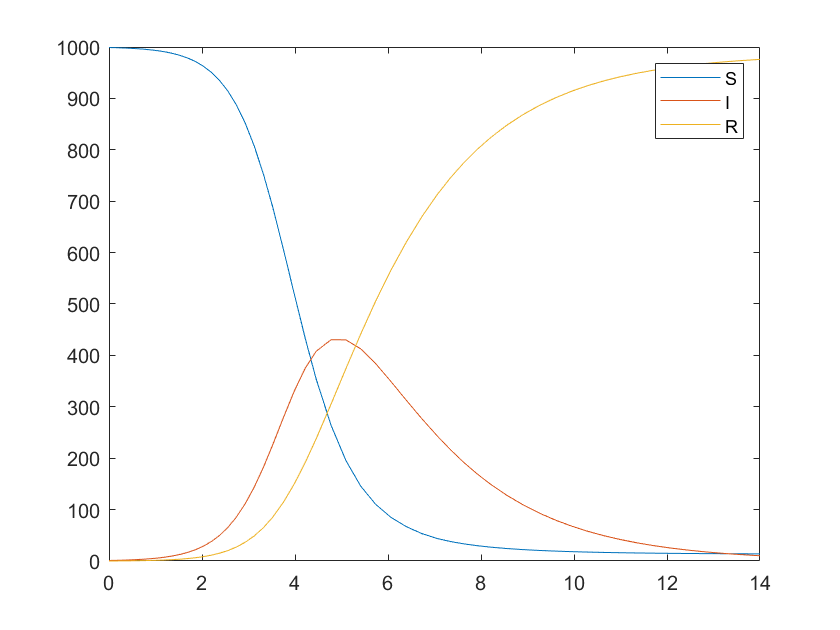


plot(tSol,S)
hold on
plot(tSol,I)
plot(tSol,R)
hold off
legend('S','I','R')


[maxI idx] = max(I)

maxI =      4.305016047814872e+02


idx =     46


peakFlu = tSol(idx)

peakFlu =    4.774746531808232



noFlu = S(end)  %persones finals no contagiades

noFlu =   13.893857323250172



%Define the ODE function SIRmodel.

function dYdt = SIRmodel(t,Y)  
    % TODO - Extract S, I, and R from input vector Y
    S = Y(1); % susceptible
    I = Y(2); % infected
    R = Y(3); % recovered
    
    % TODO - Define the constants r and a
    r = 0.00218;
    a = 0.5;
    % TODO - Define dSdt, dIdt, dRdt from the ODEs
    dSdt = -r*S*I;
    dIdt = r*S*I - a*I;
    dRdt = a*I;
    
    % TODO - Create output column vector dYdt
    dYdt = [dSdt; dIdt; dRdt];
end